# Material reproduction of piDMD via LSUN

References

- Baddoo Peter J., Herrmann Benjamin, McKeon Beverley J., Nathan Kutz J. and Brunton Steven L. 2023Physics-informed dynamic mode decompositionProc. R. Soc. A.4792022057620220576, [http://doi.org/10.1098/rspa.2022.0576](http://doi.org/10.1098/rspa.2022.0576)

- Brunton, S. L., & Kutz, J. N. (2022). *Data-Driven Science and Engineering: Machine Learning, Dynamical Systems, and Control* (2nd ed.). Cambridge: Cambridge University Press.

- jitKutz JN, Brunton SL, Brunton BW, Proctor JL. 2016 *Dynamic mode decomposition: data-driven modeling of complex systems*. Philadelphia, PA: SIAM.

clear
close all
setup

databook_matlab-master exists.
databook_DATA exists.
DATA exists.
Copying VORTALL.mat ...
piDMD-main exists.
Add path piDMD-main/src


## Source Data Preparation

nrows = 199;
ncols = 449;
load("../../../data/databook_DATA/DATA/VORTALL");
ut = reshape(VORTALL,nrows,ncols,[]);
save("../../../results/sourceflow","ut");

## TODO: Evaluate with PARFEVAL for multiple combinations of configuration parameters 

## piDMD setup

methodlist{1} = [ false, "exact" ];
methodlist{2} = [ false, "orthogonal" ];
methodlist{3} = [ true, "orthogonal" ];

## Parameter Setup

nModes4PODtrunc = 15;
varu = var(ut,0,'all');
nTrials = 3;

### Variable parameters

nCoefs4LSUNtruncSet = 1:1:4;
snRatioSet = 0.1:0.1:0.5;
ovlpFactorSet = 1:2:5;

## Configurations

Noise energy set to snRaio*100% of signal energy

iConfig = 1;
nConfigs = nTrials*...
    length(snRatioSet)*...
    (...
    2 + ... exact DMD, orthogonal DMD
    length(nCoefs4LSUNtruncSet)*length(ovlpFactorSet) ... orhogonal DMD w/ LSUN
    )

nConfigs = 210


configs = cell(nConfigs,1);
for iTrial = 1:nTrials
    config_.iTrial = iTrial;
    %
    for snRatio = snRatioSet
        config_.snRatio = snRatio;
        %
        varw = snRatio*varu;
        sigmaw = sqrt(varw);
        vt = ut + sigmaw * randn(size(ut),'like',ut);
        noisydatafile = "../../../results/noisyflow_"+replace(num2str(sigmaw),'.','_')+num2str(iTrial);
        save(noisydatafile,"vt");
        config_.noisydatafile = noisydatafile;
        %
        for imethod = 1:length(methodlist)
            islsun = strcmp(methodlist{imethod}(1),"true");
            dmdmethod = methodlist{imethod}(2);
            config_.islsun = islsun;
            config_.dmdmethod = dmdmethod;
            %
            if islsun
                for ovlpFactor = ovlpFactorSet
                    config_.ovlpFactor = ovlpFactor;
                    %
                    for nCoefs4LSUNtrunc = nCoefs4LSUNtruncSet
                        config_.nCoefs4LSUNtrunc = nCoefs4LSUNtrunc;
                        %
                        configs{iConfig} = config_;
                        iConfig = iConfig + 1;
                    end
                end
            else
                config_.nCoefs4LSUNtrunc = [];
                config_.ovlpFactor = [];
                %
                configs{iConfig} = config_;
                iConfig = iConfig + 1;
            end
        end
    end
end
configs

configs = 210×1 の cell 配列
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}


% Save configs
configsfile = "../../../results/parfevalconfigs";
save(configsfile,"configs");

## Par pool

delete(gcp('nocreate'))
pool = parpool

'Processes' プロファイルを使用して並列プール (parpool) を起動中...
18 個のワーカーをもつ並列プールに接続されています。

pool = 

 ProcessPool のプロパティ: 

            Connected: true
           NumWorkers: 18
                 Busy: false
              Cluster: 

pool.addAttachedFiles(["../../+tansacnet/+lsun/" "../../+tansacnet/+utility/" "../../mexcodes/"])

F(1:nConfigs) = parallel.FevalFuture;
for iConfig = 1:length(configs)
    config_ = configs{iConfig};
    islsun = config_.islsun;

    % Get default options
    [~,~,~,~,options] = fcn_pidmdvialsun([],[],[],islsun);

    % Conduct piDMD
    dmdmethod = config_.dmdmethod;
    if islsun
        options.ovlpFactor = config_.ovlpFactor*[1 1];
        options.nCoefs = config_.nCoefs4LSUNtrunc;
        options.useGPU = false;
    end
    %disp(options)

    S = load(config_.noisydatafile,"vt");
    vt = S.vt;

    %[rt,rmse] = myfunc_(vt,ut,dmdmethod,nModes4PODtrunc,islsun,options);
    numout = 2;
    f = parfeval(pool,@myfunc_,numout,vt,ut,dmdmethod,nModes4PODtrunc,islsun,options);
    F(iConfig) = f;

end

## Collect the results as they become available.

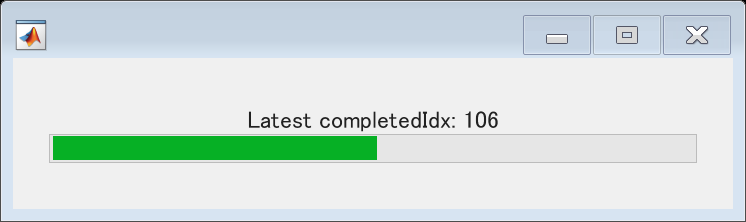

Got result with index: 001, LSUN: 0, MODE: exact, S/N: 0.10, RMSE(end): 0.090985
Got result with index: 002, LSUN: 0, MODE: orthogonal, S/N: 0.10, RMSE(end): 0.108736
Got result with index: 015, LSUN: 0, MODE: exact, S/N: 0.20, RMSE(end): 0.120685
Got result with index: 016, LSUN: 0, MODE: orthogonal, S/N: 0.20, RMSE(end): 0.173648
Got result with index: 003, LSUN: 1, MODE: orthogonal, S/N: 0.10, RMSE(end): 0.291613
Got result with index: 004, LSUN: 1, MODE: orthogonal, S/N: 0.10, RMSE(end): 0.073275
Got result with index: 006, LSUN: 1, MODE: orthogonal, S/N: 0.10, RMSE(end): 0.084443
Got result with index: 005, LSUN: 1, MODE: orthogonal, S/N: 0.10, RMSE(end): 0.080945
Got result with index: 017, LSUN: 1, MODE: orthogonal, S/N: 0.20, RMSE(end): 0.294317
Got result with index: 020, LSUN: 1, MODE: orthogonal, S/N: 0.20, RMSE(end): 0.101882
Got result with index: 019, LSUN: 1, MODE: orthogonal, S/N: 0.20, RMSE(end): 0.094593
Got result with index: 029, LSUN: 0, MODE: exact, S/N: 0.30, RMS

次を使用中のエラー: parallel.FevalFuture/fetchNext
関数評価はエラーで終了しました。

原因:
    次を使用中のエラー: fcn_pidmdvialsun
    メモリが足りません。

% Build a waitbar to track progress
h = waitbar(0,"Waiting for FevalFutures to complete...");
for iConfig = 1:nConfigs
    % fetchNext blocks until next results are available.
    [completedIdx,rt,rmse] = fetchNext(F);

    % Read configulation
    config = configs{completedIdx};
    islsun = config.islsun;
    dmdmethod = config.dmdmethod;
    snRatio = config.snRatio;
    fprintf('Got result with index: %03d, LSUN: %d, MODE: %s, S/N: %4.2f, RMSE(end): %f\n', ...
        completedIdx,islsun,dmdmethod,snRatio,rmse(end));

    % Save results
    resultfile = "../../../results/result_iConfig_"+num2str(completedIdx,"%03d");
    save(resultfile,"completedIdx","rt","rmse","config");

    % Update waitbar
    waitbar(iConfig/nConfigs,h,sprintf("Latest completedIdx: %03d", completedIdx))
end

delete(h)

% load results
%resultfile = "../../../results/result_iConfig_"+num2str(idx,"%03d");
%S = load(resultfile,"completedIdx","rt","rmse","config");
%S.completedIdx
%S.rt
%S.rmse
%S.config

## Function for evaluation

function [rt,rmse] = myfunc_(vt,ut,dmdmethod,nModes4PODtrunc,islsun,options)
%[dmdA, dmdVals, dmdVecs, dmdProjA,~,rt] = fcn_pidmdvialsun(vt,dmdmethod,nModes4PODtrunc,islsun,options);
[~,~,~,~,~,rt] = fcn_pidmdvialsun(vt,dmdmethod,nModes4PODtrunc,islsun,options);
rmse = squeeze(sqrt(mean((rt-ut).^2,[1 2])));
end